# **Project: 2D Data Frequency and Convolutional Analysis **

## 1. Phantom Image Generator

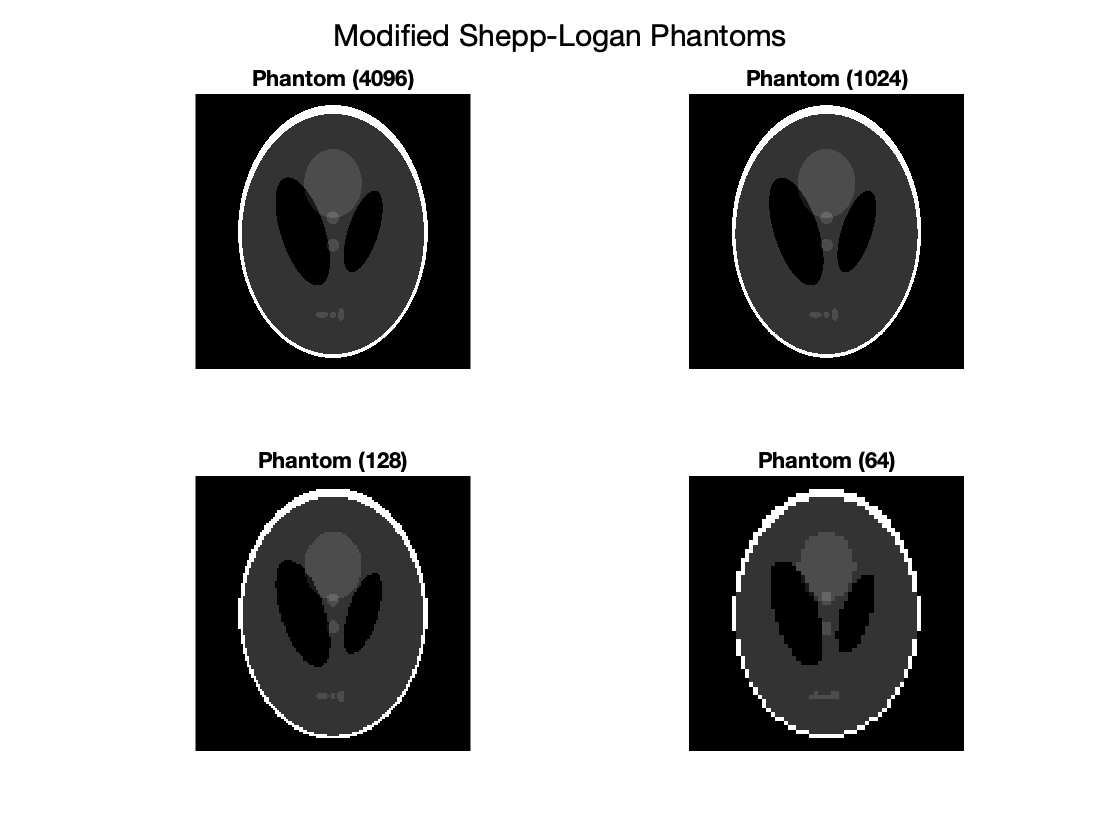

clc 
close all 
clear all 

orginalImage_4096 = phantom('Modified Shepp-Logan',4096);
orginalImage_1024 = phantom('Modified Shepp-Logan',1024);
orginalImage_128 = phantom('Modified Shepp-Logan',128);
orginalImage_64 = phantom('Modified Shepp-Logan',64); 



figure(1);
subplot(2,2,1)
imshow(orginalImage_4096), title('Phantom (4096)')
subplot(2,2,2)
imshow(orginalImage_1024), title('Phantom (1024)')
subplot(2,2,3)
imshow(orginalImage_128), title('Phantom (128)')
subplot(2,2,4)
imshow(orginalImage_64), title('Phantom (64)')
sgtitle('Modified Shepp-Logan Phantoms')

## **2. 2D FFT Implementation**

newFFT2D_4096 = FFT_2D_Function(orginalImage_4096);
newFFT2D_1024 = FFT_2D_Function(orginalImage_1024);
newFFT2D_128 = FFT_2D_Function(orginalImage_128);
newFFT2D_64 = FFT_2D_Function(orginalImage_64);


figure(2);
subplot(2,2,1)
imshow(newFFT2D_4096), title(' 4096 x 4096');

subplot(2,2,2)
imshow(newFFT2D_1024), title('1024 x 1024');

subplot(2,2,3)
imshow(newFFT2D_128), title('128 x 128');

subplot(2,2,4)
imshow(newFFT2D_64), title('64 x 64');

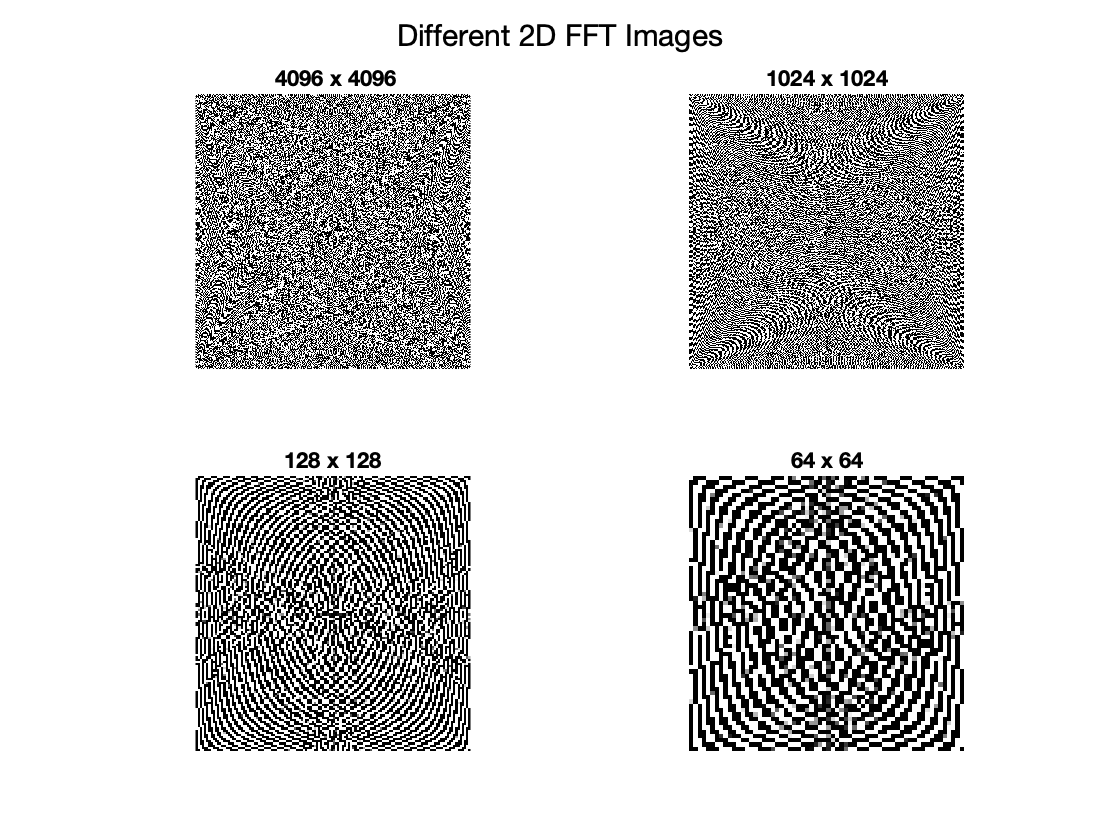


sgtitle('Different 2D FFT Images');

## **2. Verification of 2D FFT **


inv_fft2d_1024=ifft2(newFFT2D_1024); % invers of our function
inv_fft2d_64=ifft2(newFFT2D_64); % invers of our function

figure(3);
subplot(1,3,1)
imshow(orginalImage_1024), title('Org. Img.');
subplot(1,3,2);
imshow(newFFT2D_1024) ,title('FFT2D');

subplot(1,3,3)
imshow(inv_fft2d_1024), title('Inverse FFT2D ');

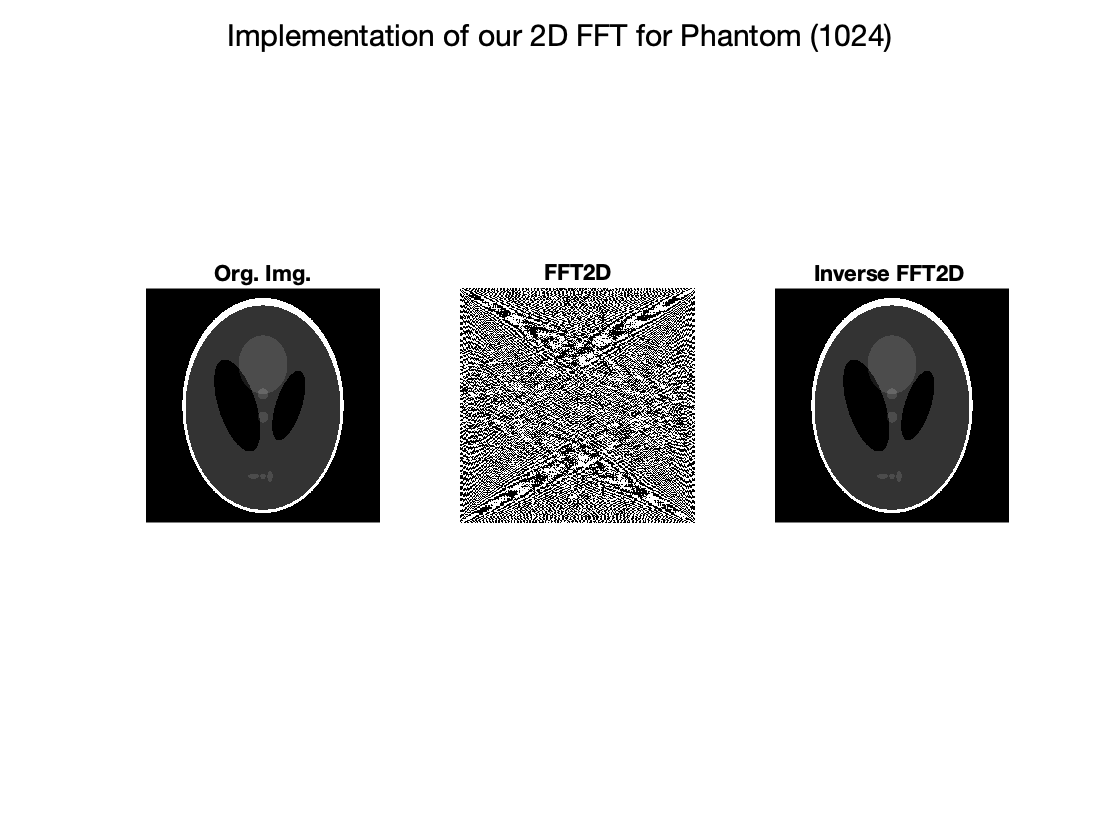

sgtitle('Implementation of our 2D FFT for Phantom (1024)')

## **2.1. Finding Difference Using Built-in Functions**

A_1024 = fft2(orginalImage_1024); % Builtin FFT2
B_1024=ifft2(A_1024); % Builtin iFFT2 

A_64 = fft2(orginalImage_64); % Builtin FFT2
B_64=ifft2(A_64); % Builtin iFFT2 

figure(4);
subplot(1,3,1)
imshow(orginalImage_1024) , title('Original Image')
subplot(1,3,2)
imshow(A_1024), title('Builtin FFT2D')

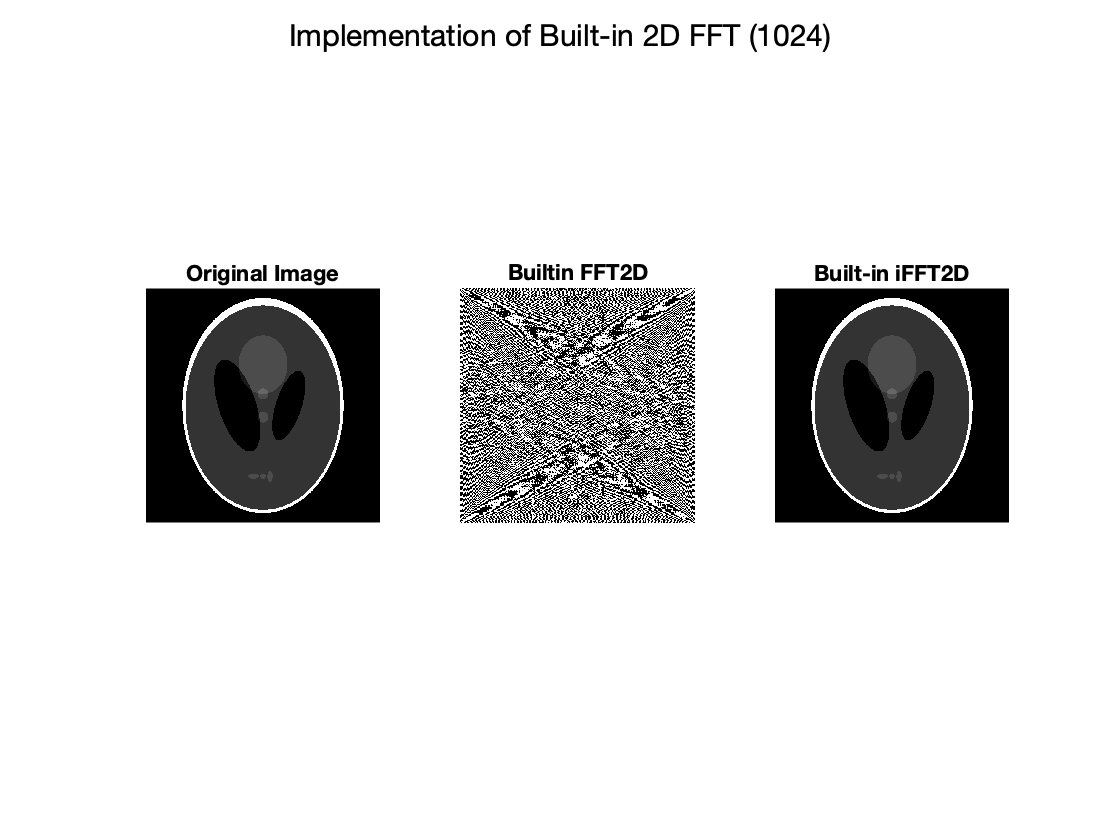

subplot(1,3,3)
imshow(B_1024), title('Built-in iFFT2D')
sgtitle('Implementation of Built-in 2D FFT (1024)')

### Comparison Between Our Function and Built-in FFT2 Function

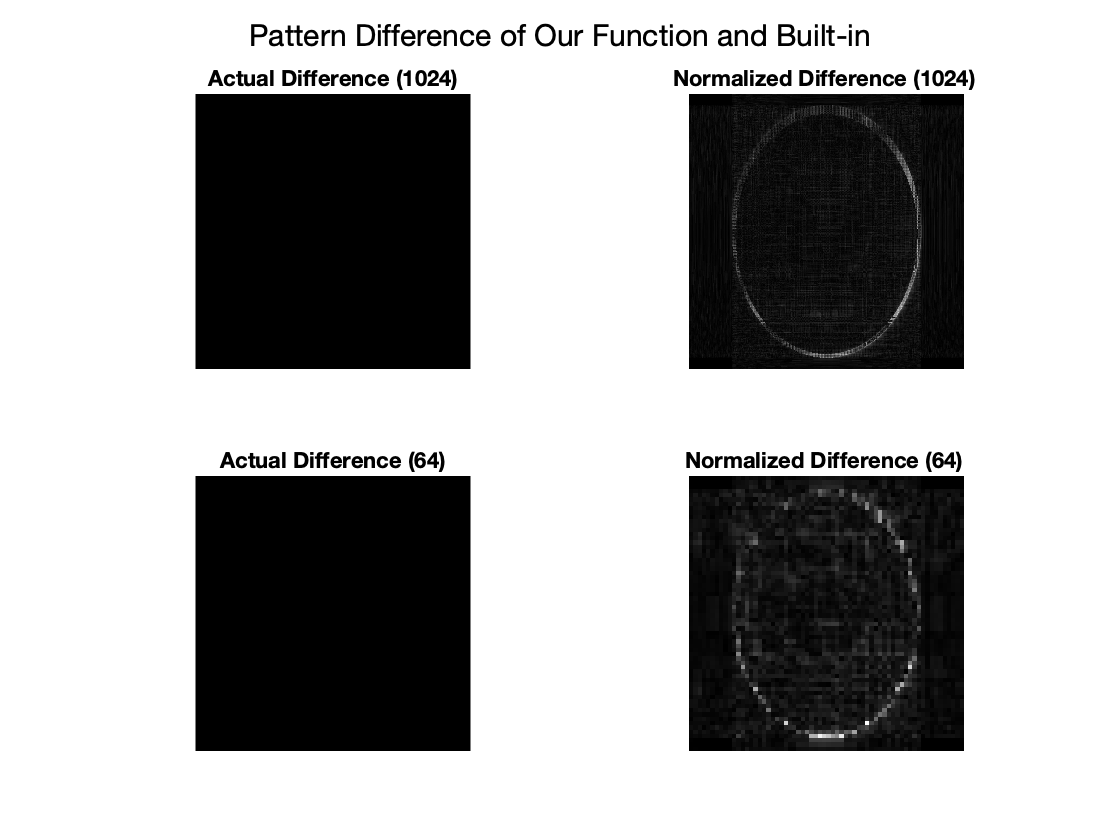

diffirence_of_my_fft2_1024 = (orginalImage_1024 - inv_fft2d_1024); % Calculation of Numerical Difference
diffirence_of_fft2_built_1024 = orginalImage_1024 - B_1024;
comparedValue_1024 = diffirence_of_my_fft2_1024 - diffirence_of_fft2_built_1024;

diffirence_of_my_fft2_64 = (orginalImage_64 - inv_fft2d_64); % Calculation of Numerical Difference
diffirence_of_fft2_built_64 = orginalImage_64 - B_64;
comparedValue_64 = diffirence_of_my_fft2_64 - diffirence_of_fft2_built_64;


figure(5);
subplot(2,2,1),
imshow(abs(comparedValue_1024)), title('Actual Difference (1024)');
subplot(2,2,2),
imshow(abs(comparedValue_1024/max(max(comparedValue_1024)))),title('Normalized Difference (1024) '); % normalized to see the pattern of differance
subplot(2,2,3),
imshow(abs(comparedValue_64)), title('Actual Difference (64)');
subplot(2,2,4),
imshow(abs(comparedValue_64/max(max(comparedValue_64)))),title('Normalized Difference (64) '); % normalized to see the pattern of differance
sgtitle('Pattern Difference of Our Function and Built-in');

# **Real-Imaginary-Magnitude- Phase**

**Real and Imaginary Part**

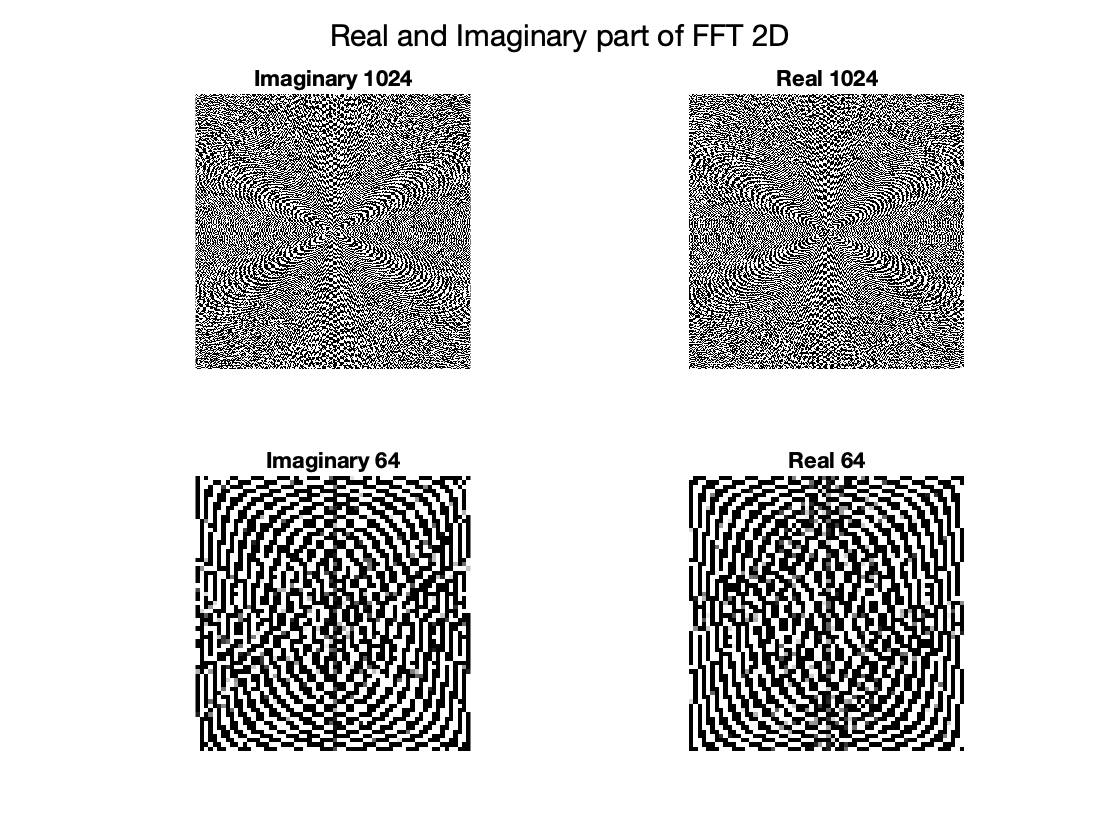

imaginary_part_1024 = imag(newFFT2D_1024);
real_part_1024 = real(newFFT2D_1024);

imaginary_part_64 = imag(newFFT2D_64);
real_part_64 = real(newFFT2D_64);


figure(6);
subplot(2,2,1)
imshow(fftshift(imaginary_part_1024)), title('Imaginary 1024')
subplot(2,2,2)
imshow(fftshift(real_part_1024)), title('Real 1024')
subplot(2,2,3)
imshow(imaginary_part_64), title('Imaginary 64')
subplot(2,2,4)
imshow(real_part_64), title('Real 64')
sgtitle('Real and Imaginary part of FFT 2D')

**Phase and Magnitude Part**

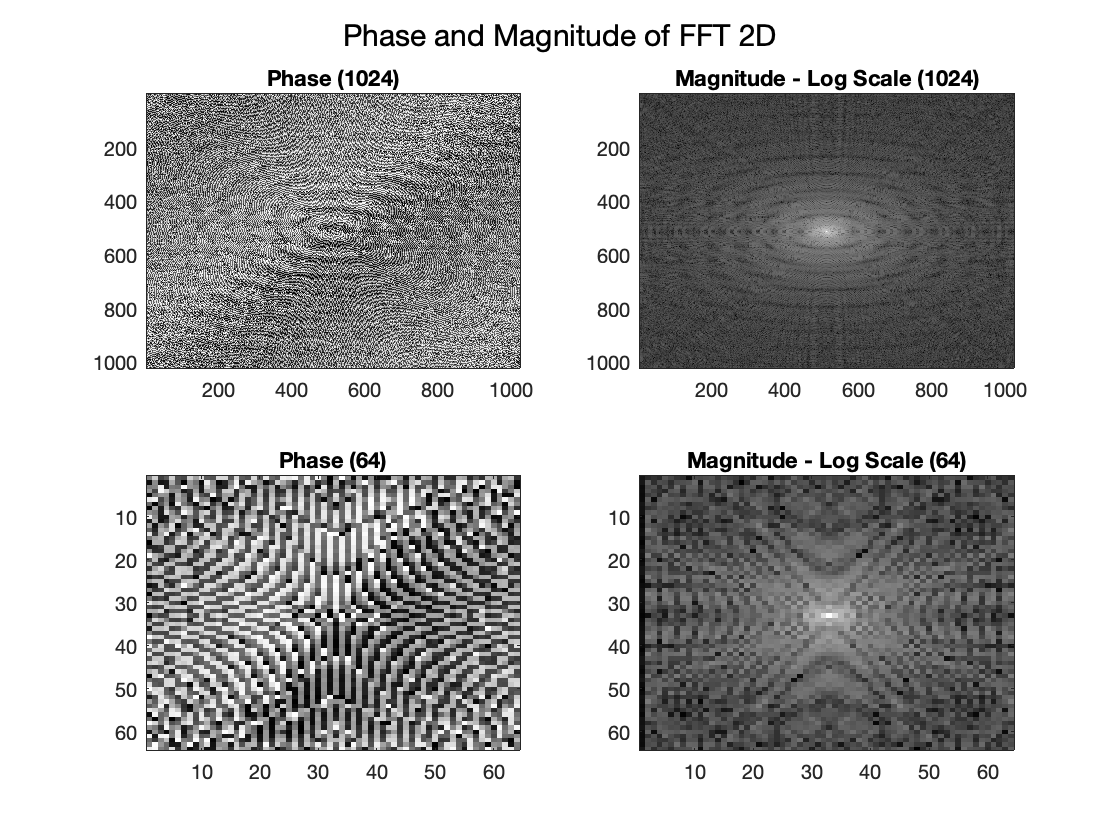

% phaseAndMagnitude function:
% Input: FFT2D of an image
% output: phase and magnitude

[phase_1024, magnitude_1024] = phaseAndMagnitude(newFFT2D_1024);
[phase_64, magnitude_64] = phaseAndMagnitude(newFFT2D_64);

figure(7);
subplot(2,2,1)
imagesc(phase_1024);  colormap(gray); title('Phase (1024)')
subplot(2,2,2)
imagesc(magnitude_1024); title('Magnitude - Log Scale (1024)')
subplot(2,2,3)
imagesc(phase_64);  colormap(gray); title('Phase (64)')
subplot(2,2,4)
imagesc(magnitude_64); title('Magnitude - Log Scale (64)')
sgtitle('Phase and Magnitude of FFT 2D')

## 3. Calculation of Energy Spectra

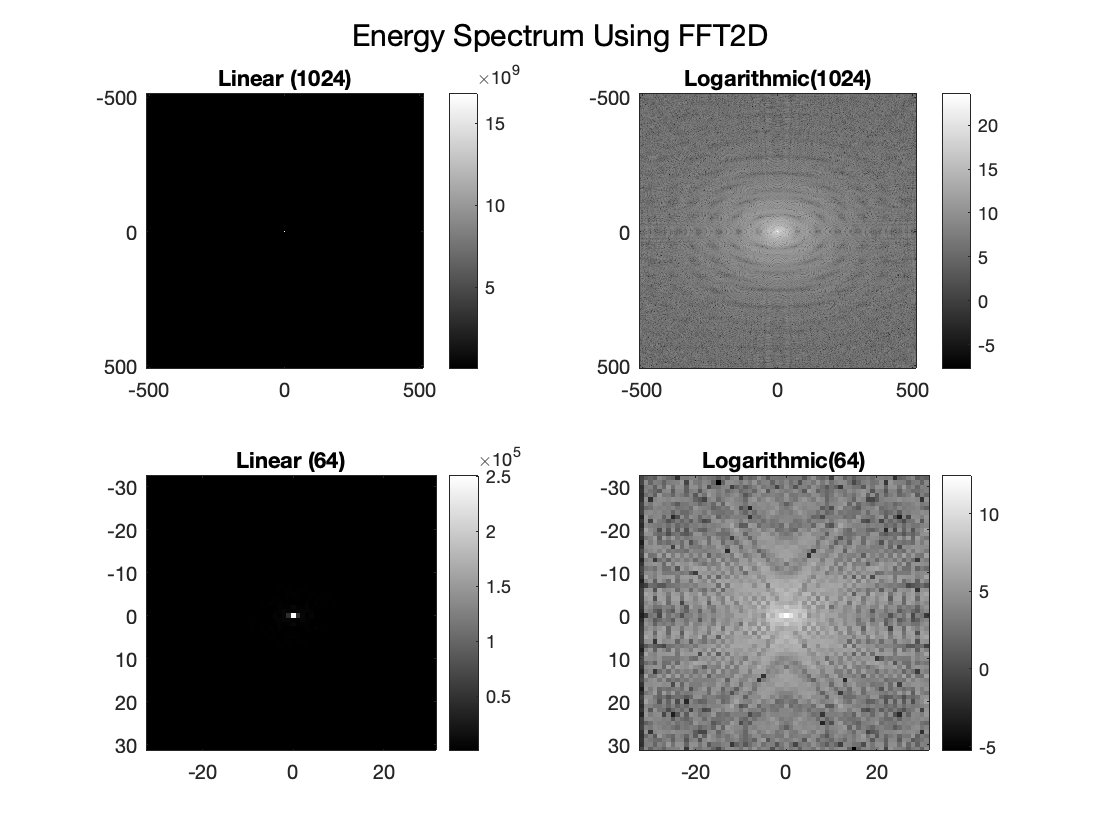

% spectrum_function :
% Input: original image and FFT2D of the image
% output: frequency and spectrum

[freq_1024,spectrum_1024] = spectrum_function(orginalImage_1024, newFFT2D_1024);
[freq_64,spectrum_64] = spectrum_function(orginalImage_64, newFFT2D_64);

figure(8);
subplot(2,2,1)
imagesc(freq_1024,freq_1024,spectrum_1024),colormap gray;colorbar ,title('Linear (1024)') % linear
subplot(2,2,2)
imagesc(freq_1024,freq_1024,log(spectrum_1024)),colormap gray;colorbar ,title('Logarithmic(1024)') % logarithmic
subplot(2,2,3)
imagesc(freq_64,freq_64,spectrum_64),colormap gray;colorbar ,title('Linear (64)') % linear
subplot(2,2,4)
imagesc(freq_64,freq_64,log(spectrum_64)),colormap gray;colorbar ,title('Logarithmic(64)') % logarithmic
sgtitle('Energy Spectrum Using FFT2D')

## 4. Filtering and apodization

### 4.1. Normal High  Band Pass Filter

% normal_High_Pass_Filter function :
% Input: original image and FFT2D of the image
% output: product of mask with FFT2D; high-pass filtered image

[filtered_fft2D_high_1024, high_pass_out_1024] = normal_High_Pass_Filter(orginalImage_1024, newFFT2D_1024);


[filtered_fft2D_high_64, high_pass_out_64] = normal_High_Pass_Filter(orginalImage_64, newFFT2D_64);

figure(9);
subplot(2, 4, 1), imshow(orginalImage_1024), title('Orginal (1024)');
subplot(2, 4, 2), imshow(newFFT2D_1024),title('FFT2D');

subplot(2, 4, 3), imshow(filtered_fft2D_high_1024), title('Filtered FFT2D');


subplot(2, 4, 4), imshow(high_pass_out_1024,[]),title('Filtered Image');

subplot(2, 4,5), imshow(orginalImage_64), title('Orginal (64)')
subplot(2, 4, 6), imshow(newFFT2D_64),title('FFT2D');

subplot(2, 4, 7), imshow(filtered_fft2D_high_64), title('Filtered FFT2D');

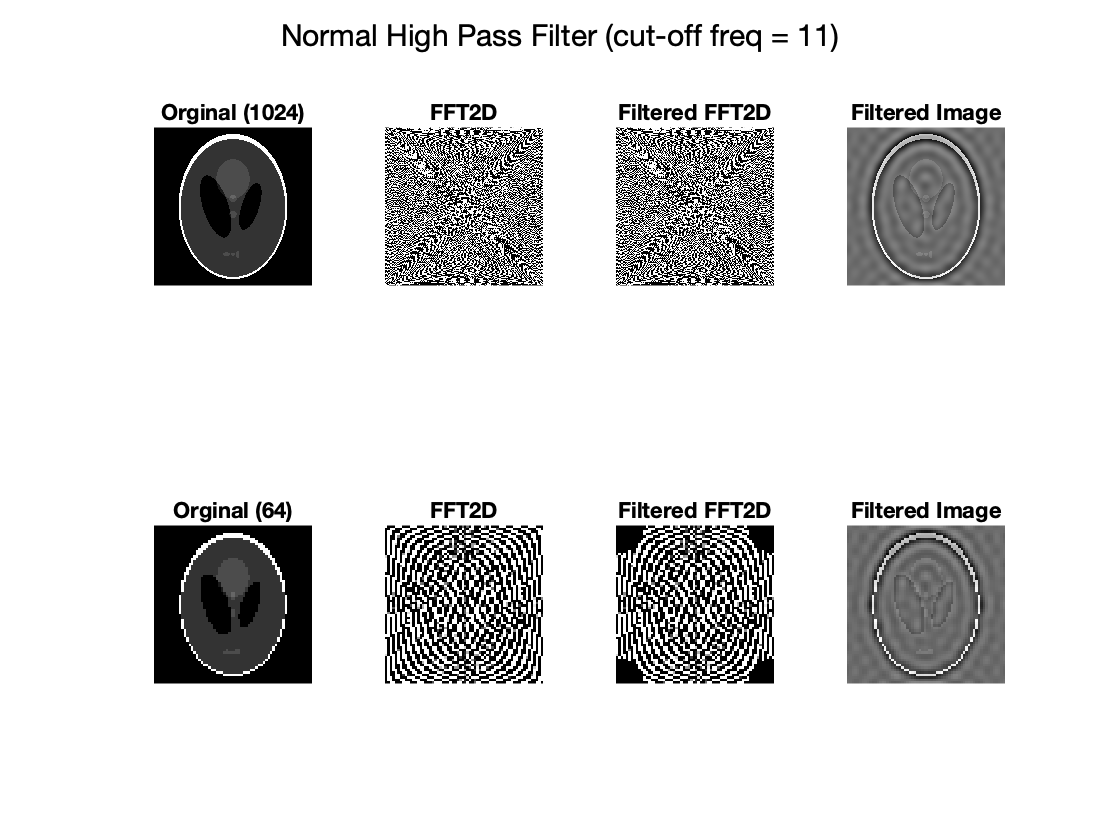

subplot(2, 4, 8), imshow(high_pass_out_64,[]),title('Filtered Image');
sgtitle('Normal High Pass Filter (cut-off freq = 11)')

### 4.2. Normal Low Band Pass Filter

% normal_Low_Pass_Filter function :
% Input: original image and FFT2D of the image
% output: product of mask with FFT2D; low-pass filtered image

[filtered_fft2D_low_1024, low_pass_out_1024] = normal_Low_Pass_Filter(orginalImage_1024, newFFT2D_1024);

[filtered_fft2D_low_64, low_pass_out_64] = normal_Low_Pass_Filter(orginalImage_64, newFFT2D_64);

figure(10);
subplot(2, 4, 1), imshow(orginalImage_1024), title('Orginal (1024)');
subplot(2, 4, 2), imshow(newFFT2D_1024),title('FFT2D');

subplot(2, 4, 3), imshow(filtered_fft2D_low_1024), title('Filtered FFT2D');


subplot(2, 4, 4), imshow(low_pass_out_1024,[]),title('Filtered Image');

subplot(2, 4,5), imshow(orginalImage_64), title('Orginal (64)')
subplot(2, 4, 6), imshow(newFFT2D_64),title('FFT2D');

subplot(2, 4, 7), imshow(filtered_fft2D_low_64), title('Filtered FFT2D');

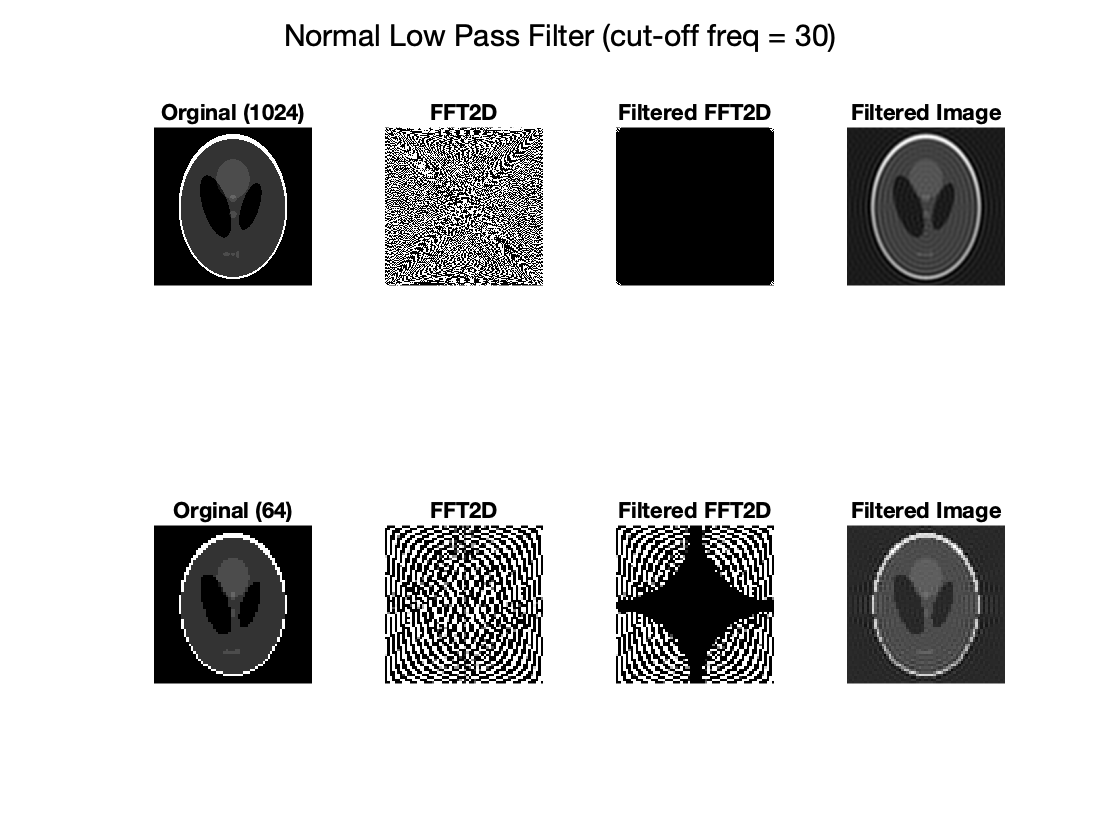

subplot(2, 4, 8), imshow(low_pass_out_64,[]),title('Filtered Image');
sgtitle('Normal Low Pass Filter (cut-off freq = 30)')

### 4.3. Butterworth High Pass Filter

% butterWorth_High_Pass_Filter function :
% Input: original image and FFT2D of the image
% output: product of mask with FFT2D; butterworth high-pass filtered image

[filtered_fft2D_bt_high_1024, bt_high_pass_out_1024] = butterWorth_High_Pass_Filter(orginalImage_1024, newFFT2D_1024);

[filtered_fft2D_bt_high_64, bt_high_pass_out_64] = butterWorth_High_Pass_Filter(orginalImage_64, newFFT2D_64);

figure(11);
subplot(2, 4, 1), imshow(orginalImage_1024), title('Orginal (1024)');
subplot(2, 4, 2), imshow(newFFT2D_1024),title('FFT2D');

subplot(2, 4, 3), imshow(filtered_fft2D_bt_high_1024), title('Filtered FFT2D');


subplot(2, 4, 4), imshow(bt_high_pass_out_1024,[]),title('Filtered Image');

subplot(2, 4,5), imshow(orginalImage_64), title('Orginal (64)')
subplot(2, 4, 6), imshow(newFFT2D_64),title('FFT2D');

subplot(2, 4, 7), imshow(filtered_fft2D_bt_high_64), title('Filtered FFT2D');

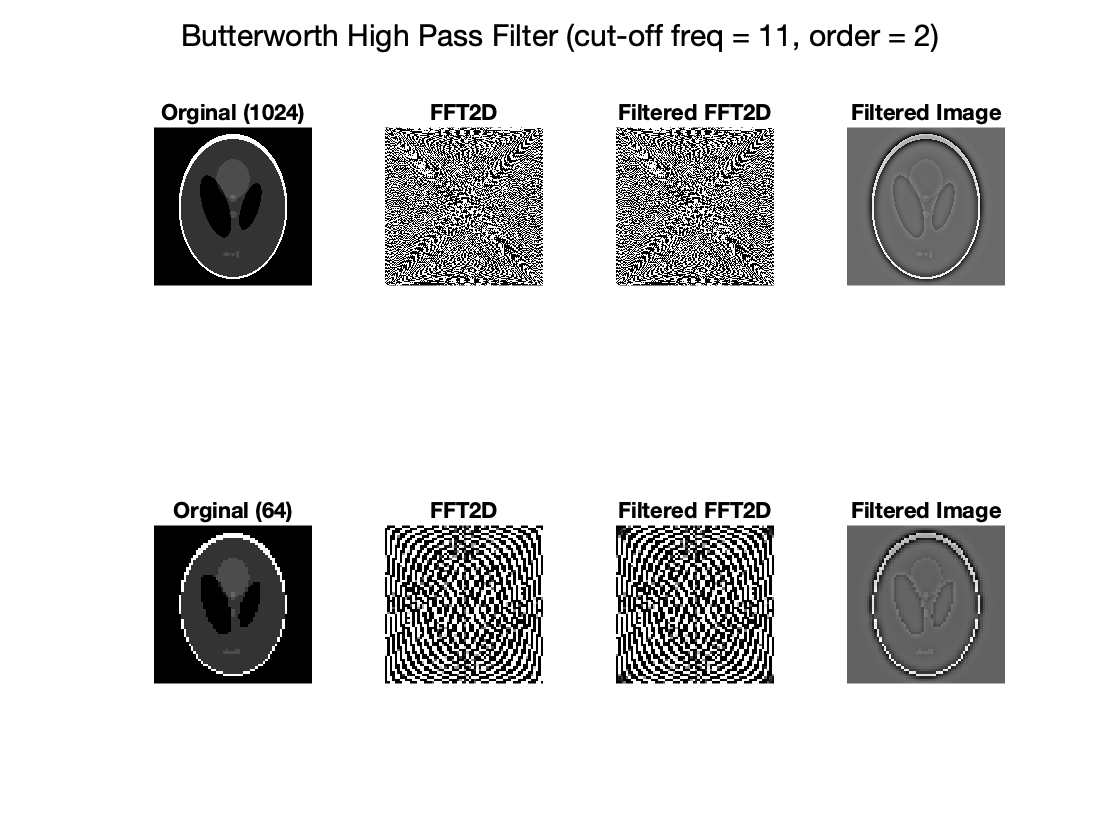

subplot(2, 4, 8), imshow(bt_high_pass_out_64,[]),title('Filtered Image');
sgtitle('Butterworth High Pass Filter (cut-off freq = 11, order = 2)')

### 4.4. Butterworth Low Pass Filter

% butterWorth_Low_Pass_Filter function :
% Input: original image and FFT2D of the image
% output: product of mask with FFT2D; butterworth low-pass filtered image

[filtered_fft2D_bt_low_1024, bt_low_pass_out_1024] = butterWorth_Low_Pass_Filter(orginalImage_1024, newFFT2D_1024);

[filtered_fft2D_bt_low_64, bt_low_pass_out_64] = butterWorth_Low_Pass_Filter(orginalImage_64, newFFT2D_64);

figure(12);
subplot(2, 4, 1); imshow(orginalImage_1024); title('Orginal (1024)');
subplot(2, 4, 2), imshow(newFFT2D_1024),title('FFT2D');

subplot(2, 4, 3), imshow(filtered_fft2D_bt_low_1024), title('Filtered FFT2D');


subplot(2, 4, 4), imshow(bt_low_pass_out_1024,[]),title('Filtered Image');

subplot(2, 4,5), imshow(orginalImage_64), title('Orginal (64)')
subplot(2, 4, 6), imshow(newFFT2D_64),title('FFT2D');

subplot(2, 4, 7), imshow(filtered_fft2D_bt_low_64), title('Filtered FFT2D');

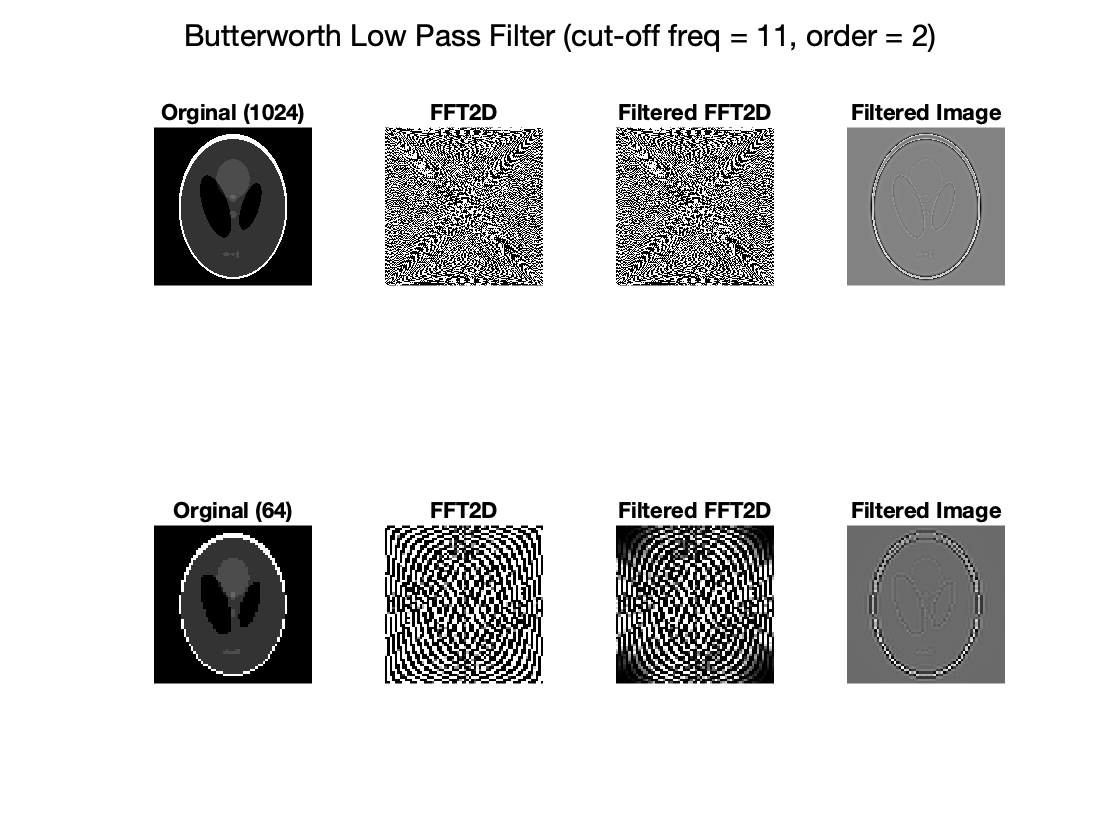

subplot(2, 4, 8), imshow(bt_low_pass_out_64,[]),title('Filtered Image');
sgtitle('Butterworth Low Pass Filter (cut-off freq = 11, order = 2)');

# 4.3 Apodizition Functions

## **4.3.1 Gausion Function**

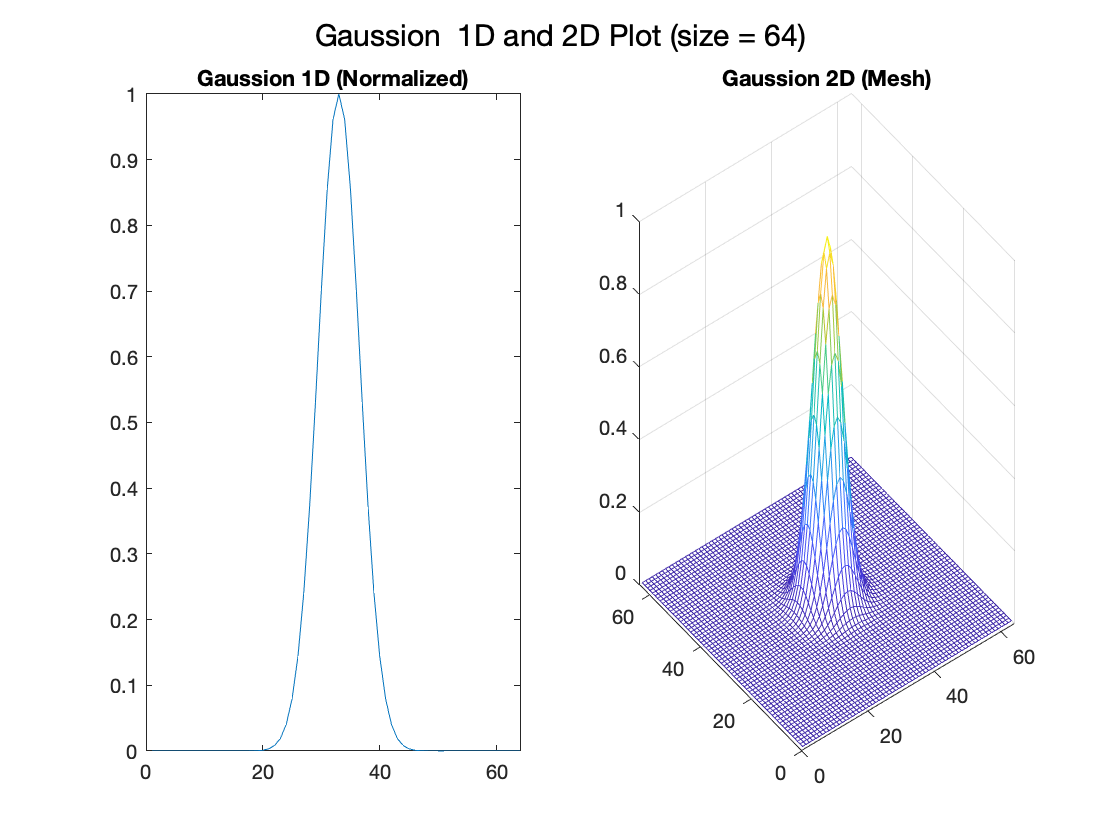

% gaussion_Function:
    % input : image
    % output: gauss1D, gauss2D, gauss2D_x_axis, gauss2D_y_axis
    
[gauss1D_64, gauss2D_64, gauss2D_x_axis_64,gauss2D_y_axis_64]= gaussion_Function(orginalImage_64);
[gauss1D_1024, gauss2D_1024, gauss2D_x_axis_1024,gauss2D_y_axis_1024]= gaussion_Function(orginalImage_1024);

figure(13);
subplot(1,2,1);
plot(gauss1D_64); xlim([0 64]); title('Gaussion 1D (Normalized)'); 
subplot(1,2,2);
mesh(gauss2D_64);  title('Gaussion 2D (Mesh)');
sgtitle('Gaussion  1D and 2D Plot (size = 64)');


filtered_gauss2D_1024 = ifft2(fftshift(FFT_2D_Function(orginalImage_1024)) .* gauss2D_1024); % element wise of matrix = density weighted filtering
filtered_gauss2D_x_axis_1024 = ifft2(fftshift(FFT_2D_Function(orginalImage_1024)) .* gauss2D_x_axis_1024);
filtered_gauss2D_y_axis_1024 = ifft2(fftshift(FFT_2D_Function(orginalImage_1024)) .* gauss2D_y_axis_1024);

filtered_gauss2D_64 = ifft2(fftshift(FFT_2D_Function(orginalImage_64)) .* gauss2D_64); % element wise of matrix = density weighted filtering
filtered_gauss2D_x_axis_64 = ifft2(fftshift(FFT_2D_Function(orginalImage_64)) .* gauss2D_x_axis_64);
filtered_gauss2D_y_axis_64 = ifft2(fftshift(FFT_2D_Function(orginalImage_64)) .* gauss2D_y_axis_64);

figure(14);
subplot(3,3,1), imshow(gauss2D_64), title('Gauss 2D');
subplot(3,3,2), imshow(gauss2D_x_axis_64), title('Gauss 2D x axis');
subplot(3,3,3), imshow(gauss2D_y_axis_64), title('Gauss 2D y axis');

subplot(3,3,4), imshow(filtered_gauss2D_1024), title('Phantom 1024')

subplot(3,3,5), imshow(filtered_gauss2D_x_axis_1024), title('x axis');

subplot(3,3,6), imshow(filtered_gauss2D_y_axis_1024), title('y axis');


subplot(3,3,7), imshow(filtered_gauss2D_64), title('Phantom 64')

subplot(3,3,8), imshow(filtered_gauss2D_x_axis_64), title('x axis');

subplot(3,3,9), imshow(filtered_gauss2D_y_axis_64), title('y axis');

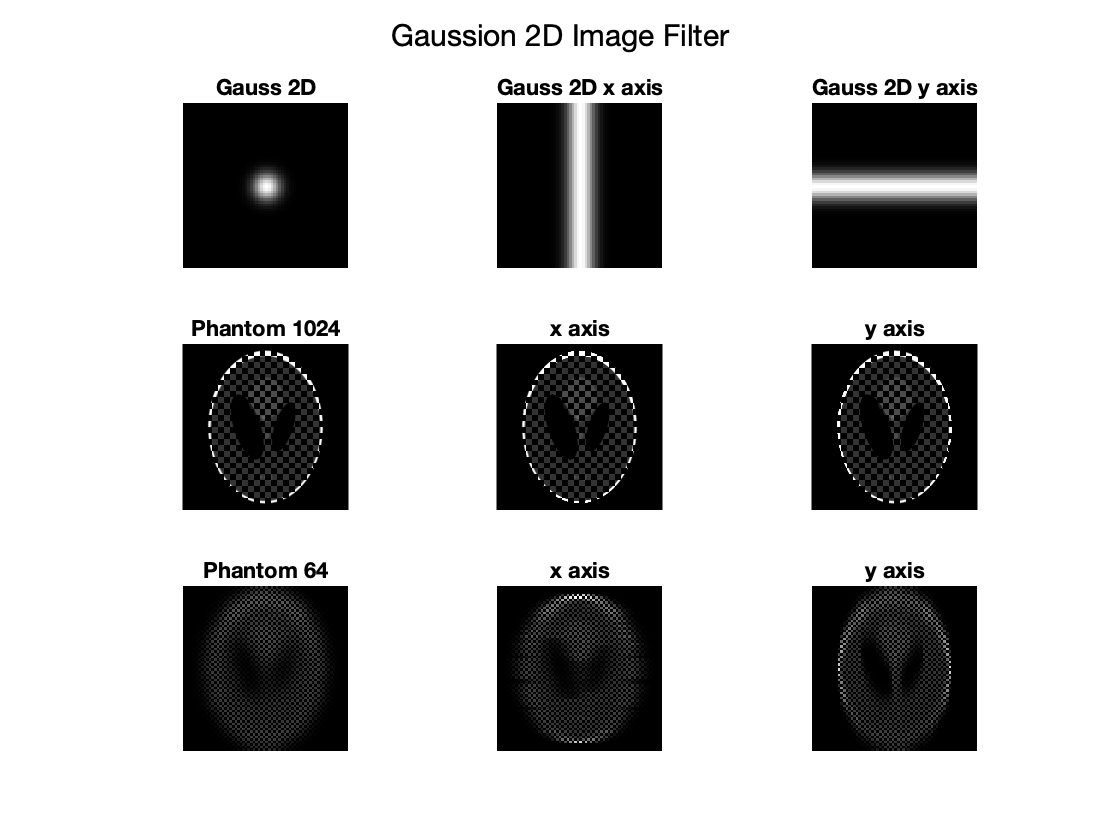

sgtitle('Gaussion 2D Image Filter');

## **4.3.2 Rectangular Function**

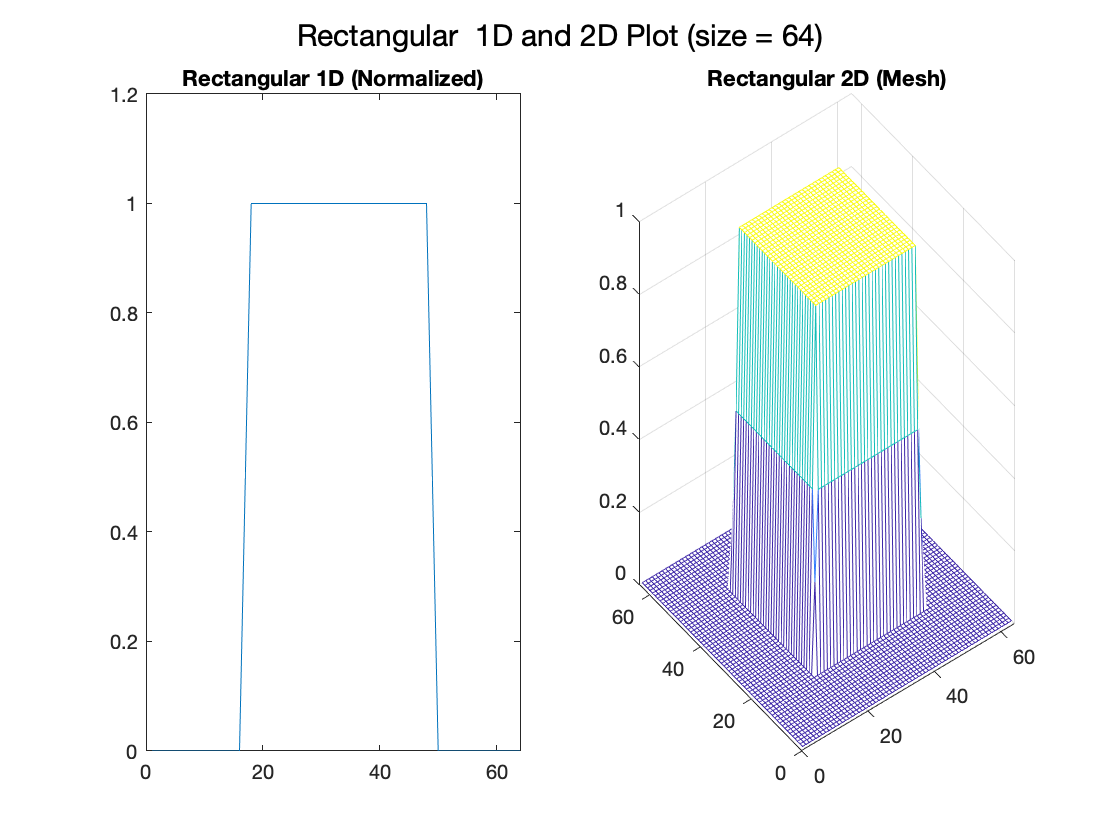

% rectangular_Function:
    % input : image
    % output: rect1D, rect2D, rect2D_x_axis, rect2D_y_axis
    
[rect1D_64, rect2D_64, rect2D_x_axis_64, rect2D_y_axis_64]= rectangular_Function(orginalImage_64);
[rect1D_1024, rect2D_1024, rect2D_x_axis_1024,rect2D_y_axis_1024]= rectangular_Function(orginalImage_1024);

figure(15);
subplot(1,2,1);
plot(rect1D_64); xlim([0 64]); ylim([0 1.2]); title('Rectangular 1D (Normalized)'); 
subplot(1,2,2);
mesh(rect2D_64);  title('Rectangular 2D (Mesh)');
sgtitle('Rectangular  1D and 2D Plot (size = 64)');


filtered_rect2D_1024 = ifft2(fftshift(FFT_2D_Function(orginalImage_1024)) .* rect2D_1024); % element wise of matrix = density weighted filtering
filtered_rect2D_x_axis_1024 = ifft2(fftshift(FFT_2D_Function(orginalImage_1024)) .* rect2D_x_axis_1024);
filtered_rect2D_y_axis_1024 = ifft2(fftshift(FFT_2D_Function(orginalImage_1024)) .* rect2D_y_axis_1024);

filtered_rect2D_64 = ifft2(fftshift(FFT_2D_Function(orginalImage_64)) .* gauss2D_64); % element wise of matrix = density weighted filtering
filtered_rect2D_x_axis_64 = ifft2(fftshift(FFT_2D_Function(orginalImage_64)) .* rect2D_x_axis_64);
filtered_rect2D_y_axis_64 = ifft2(fftshift(FFT_2D_Function(orginalImage_64)) .* rect2D_y_axis_64);

figure(16);
subplot(3,3,1), imshow(rect2D_64), title('Rect 2D');
subplot(3,3,2), imshow(rect2D_x_axis_64), title('Rect 2D x axis');
subplot(3,3,3), imshow(rect2D_y_axis_64), title('Rect 2D y axis');

subplot(3,3,4), imshow(filtered_rect2D_1024), title('Phantom 1024');

subplot(3,3,5), imshow(filtered_rect2D_x_axis_1024), title('x axis');

subplot(3,3,6), imshow(filtered_rect2D_y_axis_1024), title('y axis');


subplot(3,3,7), imshow(filtered_rect2D_64), title('Phantom 64');

subplot(3,3,8), imshow(filtered_rect2D_x_axis_64), title('x axis');

subplot(3,3,9), imshow(filtered_rect2D_y_axis_64), title('y axis');

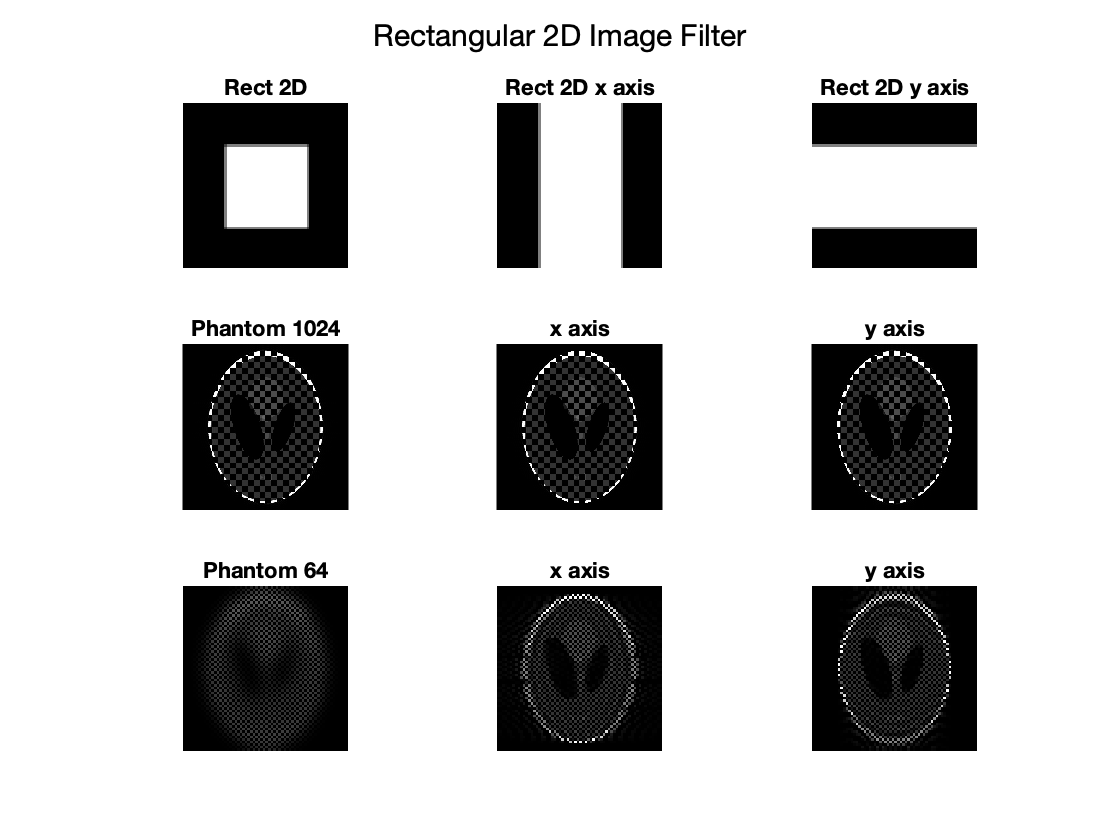

sgtitle('Rectangular 2D Image Filter');

# References

- [https://www.mathworks.com/help/images/linear-filtering.html](https://www.mathworks.com/help/images/linear-filtering.html)

- [http://www.rctn.org/bruno/npb261b/lab2/lab2.html](http://www.rctn.org/bruno/npb261b/lab2/lab2.html)

- [https://en.wikipedia.org/wiki/Butterworth_filter](https://en.wikipedia.org/wiki/Butterworth_filter)

- [http://matlab.izmiran.ru/help/toolbox/images/transf13.html](http://matlab.izmiran.ru/help/toolbox/images/transf13.html)

- [https://www.k-space.org/ymk/MIR2012_Lec3.pdf](https://www.k-space.org/ymk/MIR2012_Lec3.pdf)

- [https://stefan-k.github.io/shepplogan-rs/shepplogan/](https://stefan-k.github.io/shepplogan-rs/shepplogan/)

- [https://www.mathworks.com/matlabcentral/answers/24965-fft2-function-in-matlab](https://www.mathworks.com/matlabcentral/answers/24965-fft2-function-in-matlab)

- [https://www.researchgate.net/publication/307607352_Matlab_codes_for_2_d_DFT_without_using_fft2_and_ifft2](https://www.researchgate.net/publication/307607352_Matlab_codes_for_2_d_DFT_without_using_fft2_and_ifft2)

- [https://www.robots.ox.ac.uk/~az/lectures/ia/lect2.pdf](https://www.robots.ox.ac.uk/~az/lectures/ia/lect2.pdf)